%% set path and load some data
addpath("Calidad-imagen/")

function csvPath = guardarBarrido(imageFolder, sliceIndex)
% Procesa todas las imágenes PNG de una carpeta y guarda kcMax y SNR en CSV
% imageFolder: carpeta que contiene las imágenes
% sliceIndex: índice del slice a usar (para imágenes 3D), opcional
% csvPath: ruta del archivo CSV generado

if nargin < 2
    sliceIndex = 1; % default, si son imágenes 2D
end

% Parámetros para resolución
% pps = 64;       % tamaño de píxel proyectado (nm)
Nr = 25;
Ng = 10;
r = linspace(0,1,Nr);

% Listar imágenes en la carpeta
imgFiles = dir(fullfile(imageFolder, '*.png'));
numImages = length(imgFiles);

% Inicializar tabla de resultados
results = table('Size',[numImages 3], 'VariableTypes', {'string','double','double'}, ...
                'VariableNames', {'Filename','kcMax','SNR'});

for k = 1:numImages
    filename = imgFiles(k).name;
    filepath = fullfile(imageFolder, filename);
    
    % Leer imagen
    img = imread(filepath);
    img = im2double(img);  % convertir a double
    
    % Extraer slice si es stack 3D
    if ndims(img) == 3
        img = img(:,:,sliceIndex);
    end
    
    % Apodización de bordes (20 píxeles)
    [img_apod, ~] = apodImRect(img, 20);
    
    % Calcular kcMax
    [kcMaxVal, A0] = getDcorr(img_apod, r, Ng, 100);
    
    % SNR
    SNRVal = A0;
    
    % Guardar en tabla
    results.Filename(k) = string(filename);
    results.kcMax(k) = kcMaxVal;
    results.SNR(k) = SNRVal;
end

% Crear nombre de CSV automático
csvPath = fullfile(imageFolder, 'Resultados_kcMax_SNR.csv');

% Guardar tabla en CSV
writetable(results, csvPath);

fprintf('CSV creado correctamente: %s\n', csvPath);
end

Computing dcorr: --------------------- -- Computation done -- 
Computing dcorr: --------------------- -- Computation done -- 
Computing dcorr: --------------------- -- Computation done -- 
Computing dcorr: --------------------- -- Computation done -- 
Computing dcorr: --------------------- -- Computation done -- 
Computing dcorr: --------------------- -- Computation done -- 
Computing dcorr: --------------------- -- Computation done -- 
Computing dcorr: --------------------- -- Computation done -- 
Computing dcorr: --------------------- -- Computation done -- 
Computing dcorr: --------------------- -- Computation done -- 
Computing dcorr: --------------------- -- Computation done -- 
Computing dcorr: --------------------- -- Computation done -- 
Computing dcorr: --------------------- -- Computation done -- 
Computing dcorr: --------------------- -- Computation done -- 
Computing dcorr: --------------------- -- Computation done -- 
Computing dcorr: --------------------- -- Computation d

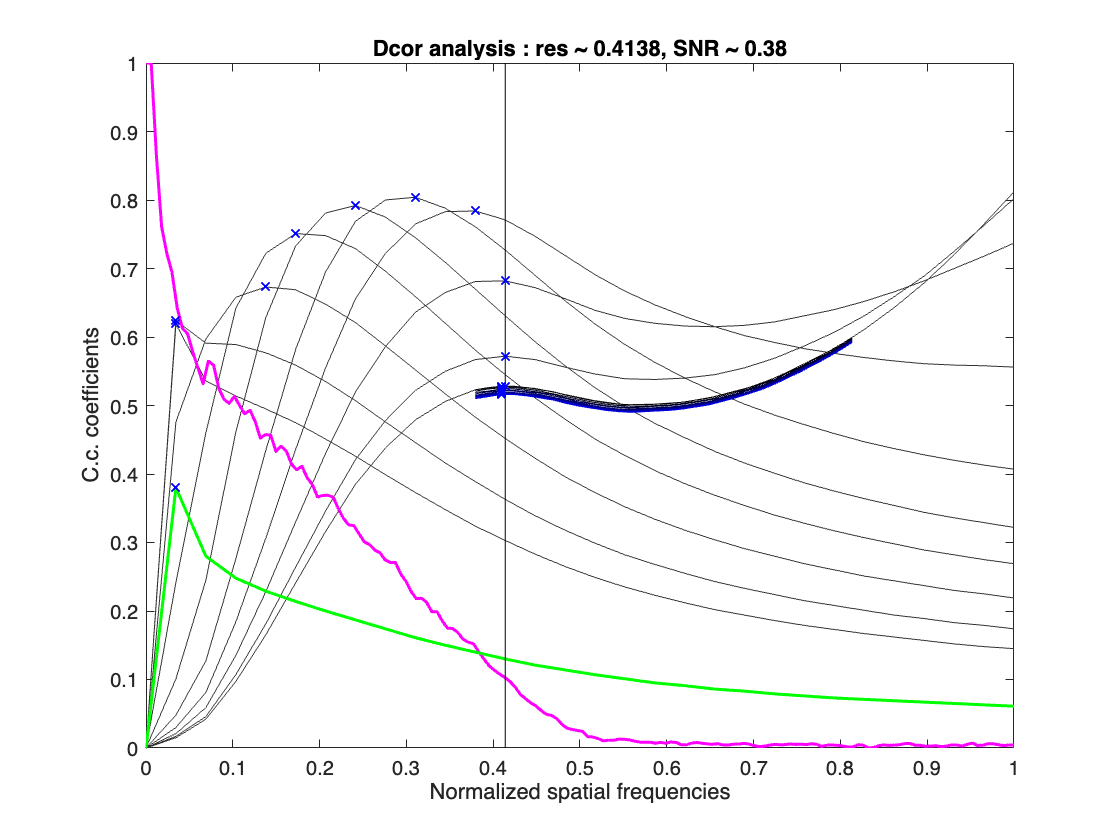

imageFolder = '/Users/yi/TFGNotebook/WBDecon_Barrido_C1';
sliceIndex = 1; % si los PNG son 2D
csvPath = guardarBarrido(imageFolder, sliceIndex);